True DoAs (deg):
  -31.1459  -21.1480   40.7115

Estimated DoAs (deg):
   40.7000  -31.1000  -21.2000

Doppler Shifts (Hz):
   1.0e+03 *

   -1.3041   -1.8570    1.2401

Estimated Velocities (m/s):
  -13.9730  -19.8964   13.2867



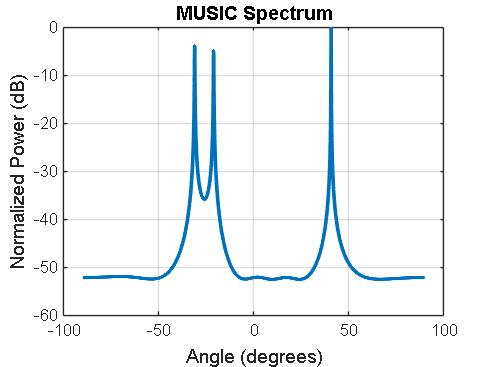

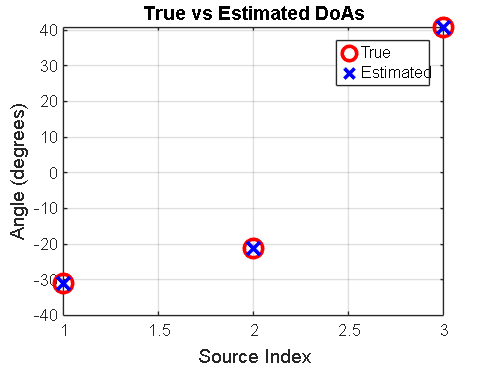

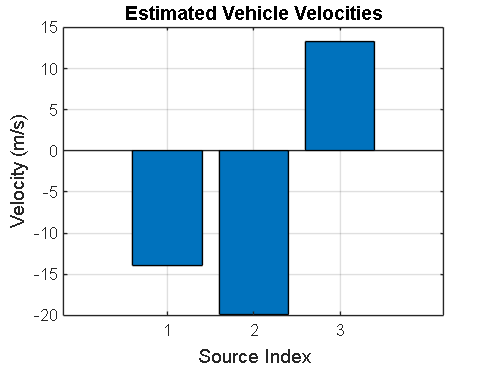

% AOA_MUSIC_V2X_STEP2.m – V2X AoA & Velocity Estimation using MUSIC

% Simulation parameters
M = 8;                      % Number of antennas
K = 3;                      % Number of sources (e.g., vehicles)
d = 0.0107 / 2;             % Distance between antennas (half-wavelength)
wavelength = 0.0107;        % Wavelength at 28 GHz (in meters)
SNR = 20;                   % Signal-to-noise ratio (dB)
fs = 1e6;                   % Sampling frequency in Hz
N = 1024;                   % Number of snapshots
c = 3e8;                    % Speed of light
fc = 28e9;                  % Carrier frequency (28 GHz)

% Generate V2X synthetic signal
[x, ~, true_DoAs, doppler_shifts] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs, fc, c);

% Estimate AoA using MUSIC
doa_estimates = algo(x, M, K, d, wavelength);

% Estimate velocities from Doppler shifts
estimated_velocities = doppler_shifts * c / fc;

% Plot results
plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts, estimated_velocities);

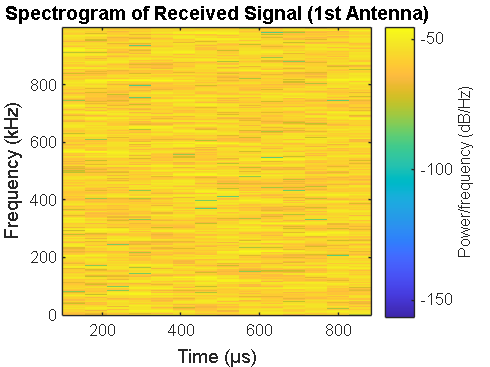


% Spectrogram visualization
figure;
spectrogram(x(1, :), 256, 200, 512, fs, 'yaxis');
title('Spectrogram of Received Signal (1st Antenna)');


%% === FUNCTIONS ===

function [x, A, true_DoAs, doppler_shifts] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs, fc, c)
    t = (0:N-1)/fs;                 % Time vector

    % Generate random DoAs and vehicle speeds
    true_DoAs = sort(-60 + 120 * rand(1, K));  % DoAs between -60° and +60°
    speeds = -30 + 60 * rand(1, K);            % Speeds between -30 and +30 m/s
    doppler_shifts = fc * speeds / c;          % Doppler shifts in Hz

    theta = deg2rad(true_DoAs);
    A = exp(-1i * 2 * pi * d * (0:M-1).' * sin(theta) / wavelength); % Steering matrix

    % Create signal with Doppler effect
    S = zeros(K, N);
    for k = 1:K
        S(k,:) = sqrt(0.5)*(randn(1,N)+1i*randn(1,N)) .* exp(1i*2*pi*doppler_shifts(k)*t);
    end

    noise_var = 10^(-SNR/10) * trace(A*(S*S')*A') / (M*N);
    noise = sqrt(noise_var/2)*(randn(M,N) + 1i*randn(M,N));
    x = A*S + noise;
end

function doa_estimates = algo(x, M, K, d, wavelength)
    theta = -90:0.1:90;
    [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    [~, idx] = sort(Pmusic, 'descend');
    idx = idx(1:K);
    initial_DoAs = theta(idx);

    doa_estimates = zeros(1, K);
    for i = 1:K
        err = @(xval) abs(1 / abs((a(xval, d, M, wavelength)' * Vn) * ...
                           (Vn' * a(xval, d, M, wavelength))) - Pmusic(idx(i)));
        doa_estimates(i) = fminsearch(err, initial_DoAs(i));
    end
end

function a_vec = a(angle, d, M, wavelength)
    a_vec = exp(-1i * 2 * pi * d * (0:M-1).' * sind(angle) / wavelength);
end

function [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta)
    Rxx = (x * x') / size(x, 2);
    [V, D] = eig(Rxx);
    [~, idx] = sort(diag(D), 'descend');
    V = V(:, idx);
    Vn = V(:, K+1:end);

    Pmusic = arrayfun(@(ang) 1 / abs((a(ang, d, M, wavelength)' * Vn) * ...
                                     (Vn' * a(ang, d, M, wavelength))), theta);
end

function plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts, estimated_velocities)
    theta = -90:0.1:90;
    [~, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    disp('True DoAs (deg):'); disp(true_DoAs);
    disp('Estimated DoAs (deg):'); disp(doa_estimates);
    disp('Doppler Shifts (Hz):'); disp(doppler_shifts);
    disp('Estimated Velocities (m/s):'); disp(estimated_velocities);

    % MUSIC Spectrum Plot
    figure;
    plot(theta, 10*log10(abs(Pmusic)/max(abs(Pmusic))), 'LineWidth', 2);
    xlabel('Angle (degrees)');
    ylabel('Normalized Power (dB)');
    title('MUSIC Spectrum');
    grid on;

    % DoA Comparison Plot
    figure;
    plot(1:K, sort(true_DoAs), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
    hold on;
    plot(1:K, sort(doa_estimates), 'bx', 'LineWidth', 2, 'MarkerSize', 10);
    xlabel('Source Index');
    ylabel('Angle (degrees)');
    title('True vs Estimated DoAs');
    legend('True', 'Estimated');
    grid on;

    % Velocity Estimation Plot
    figure;
    bar(1:K, estimated_velocities);
    xlabel('Source Index');
    ylabel('Velocity (m/s)');
    title('Estimated Vehicle Velocities');
    grid on;
end
